clear; clc; close all;

%% ========================================================================
%  第一部分: 参数设置
%% ========================================================================
fprintf('========================================\n');

fprintf('可见光定位与航迹规划仿真系统（考虑不可透光障碍物）\n');

可见光定位与航迹规划仿真系统（考虑不可透光障碍物）


fprintf('========================================\n\n');


% --- 环境参数 ---
room_size = [4, 4, 4];          % [长, 宽, 高] 米
grid_size = 16;                 % 16x16参考点网格 (VLP指纹库 和 A*地图 共用)
grid_spacing = room_size(1) / grid_size;  % 0.25米

% --- LED发射端参数 ---
LED_pos = [1, 1, 4;     % LED1位置
           1, 3, 4;     % LED2位置
           3, 3, 4;     % LED3位置
           3, 1, 4];    % LED4位置
num_LED = size(LED_pos, 1);

% LED调制频率输入
fprintf('请输入4个LED的调制频率 (Hz):\n');

请输入4个LED的调制频率 (Hz):


LED_freq = input('例如 [1000, 2000, 3000, 4000]: ');
if isempty(LED_freq) || length(LED_freq) ~= 4
    LED_freq = [1000, 2000, 3000, 4000];
    fprintf('使用默认频率: [1000, 2000, 3000, 4000] Hz\n');
end

使用默认频率: [1000, 2000, 3000, 4000] Hz



P_tx     = 1;           % LED发射功率 (W)
m_lambert = 1;          % 朗伯辐射模型阶数 (对应半功率角60度)

% --- PD接收端参数 ---
A_pd   = 1e-4;          % PD物理面积 (1cm² = 1e-4 m²)
FOV    = 70;            % 视场角 (度)
FOV_rad = deg2rad(FOV); % 转换为弧度
R_pd   = 0.5;           % PD响应度 (A/W)
Ts     = 1;             % 光学滤波器增益
n_refract = 1.5;        % 光学集中器折射率
g_con  = n_refract^2 / sin(FOV_rad)^2;  % 光学集中器增益 ≈ 2.55

% --- 信道和噪声参数 ---
rho_wall = 0.8;         % 墙面反射率
N_wall   = 20;          % 墙面离散化: 20x20网格
Fs       = 120e3;       % 采样频率 (120 kHz)
B        = Fs / 2;      % 系统带宽 (60 kHz)
N_DFT    = 1024;        % DFT点数
q        = 1.602e-19;   % 基本电荷 (C)
k_B      = 1.38e-23;    % 玻尔兹曼常数 (J/K)
T_abs    = 295;         % 绝对温度 (K)
R_L      = 10e3;        % 负载电阻 (10 kΩ)
I_bg     = 260e-6;      % 背景光电流 (260 μA)

% --- 算法参数 ---
K_values = [3, 4, 5];   % 测试不同K值
num_test = 100;         % 测试点数量

%% ===== 航迹规划参数 (A*) =====
fprintf('\n--- 航迹规划设置 ---\n');


--- 航迹规划设置 ---



% 1. 设置障碍物（不可透光，从地面到房顶）
% 格式: [x_min, x_max, y_min, y_max]
fprintf('请输入3个障碍物区域 (每行一个, 格式 [xmin xmax ymin ymax]):\n');

请输入3个障碍物区域 (每行一个, 格式 [xmin xmax ymin ymax]):


obstacles_input = input('例如 [1 1.5 1 3; ...]: ');
if isempty(obstacles_input) || size(obstacles_input,1) ~= 3 || size(obstacles_input,2) ~= 4
    obstacles = [1.0, 1.5, 0.5, 2.0;   % 障碍物1
                 2.0, 2.5, 2.5, 3.5;   % 障碍物2
                 3.0, 3.5, 0.5, 1.5];  % 障碍物3
    fprintf('使用默认障碍物。\n');
else
    obstacles = obstacles_input;
end

使用默认障碍物。



% 2. 设置目标点
Goal_pos_meters = input('请输入目标点坐标 [x, y]: ');
if isempty(Goal_pos_meters) || length(Goal_pos_meters) ~= 2
    Goal_pos_meters = [0.5, 0.5];
    fprintf('使用默认目标点: [%.1f, %.1f]\n', Goal_pos_meters(1), Goal_pos_meters(2));
end

使用默认目标点: [0.5, 0.5]



fprintf('\n参数设置完成!\n');


参数设置完成!


fprintf('LED频率: %.0f, %.0f, %.0f, %.0f Hz\n', LED_freq);

LED频率: 1000, 2000, 3000, 4000 Hz


fprintf('开始构建指纹库...\n\n');

开始构建指纹库...




%% ========================================================================
%  第二部分: 离线阶段 - 指纹库构建（考虑障碍物遮挡）
%% ========================================================================

% 创建参考点网格（先生成完整16×16，再剔除障碍物内部的点）
x_grid = ((1:grid_size) - 0.5) * grid_spacing;
y_grid = ((1:grid_size) - 0.5) * grid_spacing;
[X_RP, Y_RP] = meshgrid(x_grid, y_grid);
RP_coords = [X_RP(:), Y_RP(:), zeros(grid_size^2, 1)];  % 256x3矩阵
num_RP = size(RP_coords, 1);

% ===== 去除落在障碍物内部的参考点 =====
valid_RP = true(num_RP, 1);
for i_obs = 1:size(obstacles, 1)
    obs  = obstacles(i_obs, :);    % [xmin xmax ymin ymax]
    xmin = obs(1); xmax = obs(2);
    ymin = obs(3); ymax = obs(4);

    inside = RP_coords(:,1) >= xmin & RP_coords(:,1) <= xmax & ...
             RP_coords(:,2) >= ymin & RP_coords(:,2) <= ymax;
    valid_RP = valid_RP & ~inside;
end
RP_coords = RP_coords(valid_RP, :);    % 只保留有效参考点
num_RP    = size(RP_coords, 1);

% 初始化指纹库
fingerprint_DB = zeros(num_RP, 6);  % [x, y, RSS1, RSS2, RSS3, RSS4]
fingerprint_DB(:, 1:2) = RP_coords(:, 1:2);

% 预计算墙面反射单元
wall_elements = generate_wall_elements(room_size, N_wall);

% 进度条
fprintf('构建指纹库进度:\n');

构建指纹库进度:


h = waitbar(0, '计算参考点指纹...');

for i = 1:num_RP
    RP_pos = RP_coords(i, :);
    RSS_vector = zeros(1, num_LED);
    I_sig_total = 0;

    % 遍历每个LED
    for k = 1:num_LED
        LED_k = LED_pos(k, :);

        % 计算LOS增益（考虑障碍物遮挡）
        H_LOS = calculate_LOS_gain(LED_k, RP_pos, m_lambert, A_pd, ...
                                   Ts, g_con, FOV_rad, obstacles);

        % 计算NLOS增益 (一次反射，不考虑障碍物遮挡)
        H_NLOS = calculate_NLOS_gain(LED_k, RP_pos, wall_elements, ...
                                     rho_wall, m_lambert, A_pd, Ts, g_con, FOV_rad);

        % 总信道增益
        H_total = H_LOS + H_NLOS;

        % 接收光功率和信号电流
        P_rx = P_tx * H_total;
        I_sig = R_pd * P_rx;
        I_sig_total = I_sig_total + I_sig;

        RSS_vector(k) = I_sig;
    end

    % 计算噪声
    sigma_shot2    = 2 * q * (I_sig_total + I_bg) * B;
    sigma_thermal2 = (4 * k_B * T_abs / R_L) * B;
    sigma_total2   = sigma_shot2 + sigma_thermal2;
    sigma_bin      = sqrt(sigma_total2 / (N_DFT / 2));

    % 添加高斯噪声生成指纹
    RSS_noisy = RSS_vector + sigma_bin * randn(1, num_LED);
    fingerprint_DB(i, 3:6) = RSS_noisy;

    % 更新进度
    if mod(i, 10) == 0 || i == num_RP
        waitbar(i/num_RP, h, ...
            sprintf('已完成: %d/%d (%.1f%%)', i, num_RP, 100*i/num_RP));
    end
end

close(h);
fprintf('指纹库构建完成! (有效参考点数量: %d)\n\n', num_RP);

指纹库构建完成! (有效参考点数量: 228)




%% ========================================================================
%  第三部分: 在线阶段 - WKNN定位测试（考虑障碍物遮挡）
%% ========================================================================

fprintf('开始在线定位测试...\n');

开始在线定位测试...


fprintf('测试点数量: %d\n', num_test);

测试点数量: 100


fprintf('K值范围: %s\n\n', mat2str(K_values));

K值范围: [3 4 5]




% 初始化结果存储
results = struct();
for k_idx = 1:length(K_values)
    K = K_values(k_idx);
    results(k_idx).K       = K;
    results(k_idx).errors  = zeros(num_test, 1);
    results(k_idx).true_pos = zeros(num_test, 2);
    results(k_idx).est_pos  = zeros(num_test, 2);
end

% 进度条
h = waitbar(0, '定位测试中...');

for t = 1:num_test
    % 1. 生成一个不在障碍物内的测试点（TP_true）
    margin = 0.3;
    while true
        TP_candidate = [margin + (room_size(1)-2*margin)*rand(), ...
                        margin + (room_size(2)-2*margin)*rand(), 0];

        % 检查该点是否在任何一个障碍物内
        is_in_obstacle = false;
        for obs_idx = 1:size(obstacles, 1)
            obs = obstacles(obs_idx, :); % [xmin xmax ymin ymax]
            if (TP_candidate(1) >= obs(1) && TP_candidate(1) <= obs(2) && ...
                TP_candidate(2) >= obs(3) && TP_candidate(2) <= obs(4))
                is_in_obstacle = true;
                break;
            end
        end

        if ~is_in_obstacle
            TP_true = TP_candidate;
            break;
        end
    end

    % 2. 计算测试点的RSS指纹（考虑LOS遮挡）
    RSS_measured = zeros(1, num_LED);
    I_sig_total = 0;

    for k = 1:num_LED
        LED_k = LED_pos(k, :);

        H_LOS = calculate_LOS_gain(LED_k, TP_true, m_lambert, A_pd, ...
                                   Ts, g_con, FOV_rad, obstacles);

        H_NLOS = calculate_NLOS_gain(LED_k, TP_true, wall_elements, rho_wall, ...
                                     m_lambert, A_pd, Ts, g_con, FOV_rad);

        H_total = H_LOS + H_NLOS;
        P_rx    = P_tx * H_total;
        I_sig   = R_pd * P_rx;
        I_sig_total = I_sig_total + I_sig;
        RSS_measured(k) = I_sig;
    end

    % 添加噪声
    sigma_shot2    = 2 * q * (I_sig_total + I_bg) * B;
    sigma_thermal2 = (4 * k_B * T_abs / R_L) * B;
    sigma_total2   = sigma_shot2 + sigma_thermal2;
    sigma_bin      = sqrt(sigma_total2 / (N_DFT / 2));
    RSS_measured   = RSS_measured + sigma_bin * randn(1, num_LED);

    % 3. 对不同K值执行WKNN
    for k_idx = 1:length(K_values)
        K = K_values(k_idx);
        TP_est = WKNN_positioning(RSS_measured, fingerprint_DB, K);

        error_val = norm(TP_true(1:2) - TP_est);
        results(k_idx).errors(t)   = error_val;
        results(k_idx).true_pos(t, :) = TP_true(1:2);
        results(k_idx).est_pos(t, :)  = TP_est;
    end

    if mod(t, 10) == 0 || t == num_test
        waitbar(t/num_test, h, sprintf('测试进度: %d/%d', t, num_test));
    end
end

close(h);
fprintf('定位测试完成!\n\n');

定位测试完成!




%% ========================================================================
%  第四部分: A* 航迹规划（基于障碍物栅格）
%% ========================================================================

fprintf('开始A*航迹规划...\n');

开始A*航迹规划...



% 1. 创建A*栅格地图 (0=可通行, 1=障碍)
AStar_map = zeros(grid_size, grid_size);

% 2. 栅格化障碍物
for i = 1:size(obstacles, 1)
    obs = obstacles(i, :);
    x_min_idx = max(1, ceil(obs(1) / grid_spacing));
    x_max_idx = min(grid_size, ceil(obs(2) / grid_spacing));
    y_min_idx = max(1, ceil(obs(3) / grid_spacing));
    y_max_idx = min(grid_size, ceil(obs(4) / grid_spacing));

    AStar_map(y_min_idx:y_max_idx, x_min_idx:x_max_idx) = 1;
end

% 3. 获取起点和终点（起点: 使用K=4最后一个测试点的估计位置）
K_demo_idx = 2;  % 对应 K=4 (K_values = [3,4,5])
Start_pos_meters = results(K_demo_idx).est_pos(end, :); % [x, y]
Goal_pos_meters_plot = Goal_pos_meters;                 % [x, y]

% 4. 转换起点/终点为栅格索引 [行, 列]
Start_node = [min(grid_size, max(1, ceil(Start_pos_meters(2) / grid_spacing))), ...
              min(grid_size, max(1, ceil(Start_pos_meters(1) / grid_spacing)))];

Goal_node  = [min(grid_size, max(1, ceil(Goal_pos_meters_plot(2) / grid_spacing))), ...
              min(grid_size, max(1, ceil(Goal_pos_meters_plot(1) / grid_spacing)))];

% 5. 检查起点或终点是否在障碍物内
if AStar_map(Start_node(1), Start_node(2)) == 1
    fprintf('警告: 起点在障碍物内! 规划可能失败。\n');
end
if AStar_map(Goal_node(1), Goal_node(2)) == 1
    fprintf('警告: 终点在障碍物内! 规划可能失败。\n');
end

% 6. 执行A*算法
[path_indices, path_found] = AStar_pathfinding(AStar_map, Start_node, Goal_node);

% 7. 转换路径回米坐标 (用于绘图)
path_meters = [];
if path_found
    fprintf('A* 路径已找到! (共 %d 个步骤)\n', size(path_indices, 1));
    path_rows = path_indices(:, 1);
    path_cols = path_indices(:, 2);
    path_meters = [(path_cols - 0.5) * grid_spacing, ...
                   (path_rows - 0.5) * grid_spacing];
else
    fprintf('A* 未找到路径!\n');
end

A* 路径已找到! (共 13 个步骤)



fprintf('航迹规划完成!\n\n');

航迹规划完成!




%% ========================================================================
%  第五部分: 结果可视化
%% ========================================================================

fprintf('生成可视化结果...\n');

生成可视化结果...


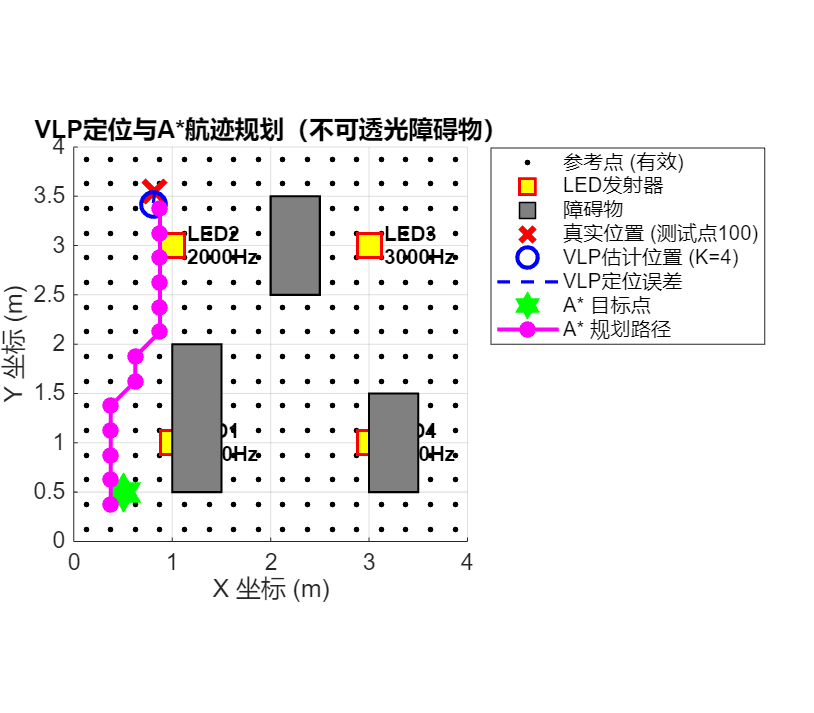


% ===== 图1: 仿真场景、定位与航迹规划 =====
figure('Name', 'VLP定位与A*航迹规划', 'Position', [100, 100, 800, 700]);
hold on; grid on; axis equal;

% 绘制参考点（有效 RP）
plot(fingerprint_DB(:,1), fingerprint_DB(:,2), 'k.', 'MarkerSize', 8, ...
     'DisplayName', '参考点 (有效)');

% 绘制LED位置
plot(LED_pos(:,1), LED_pos(:,2), 'rs', 'MarkerSize', 15, ...
     'LineWidth', 2, 'MarkerFaceColor', 'y', 'DisplayName', 'LED发射器');

% 标注LED
for i = 1:num_LED
    text(LED_pos(i,1)+0.15, LED_pos(i,2), sprintf('LED%d\n%.0fHz', i, LED_freq(i)), ...
         'FontSize', 10, 'FontWeight', 'bold');
end

% 绘制障碍物（灰色矩形）
for i = 1:size(obstacles, 1)
    obs = obstacles(i, :);
    x = obs(1);
    y = obs(3);
    w = obs(2) - obs(1);
    h = obs(4) - obs(3);
    rectangle('Position', [x, y, w, h], 'FaceColor', [0.5 0.5 0.5], ...
              'EdgeColor', 'k', 'LineWidth', 1);
end
% 为障碍物添加图例句柄
plot(NaN, NaN, 's', 'MarkerFaceColor', [0.5 0.5 0.5], ...
    'MarkerEdgeColor', 'k', 'LineWidth', 1, 'MarkerSize', 10, ...
    'DisplayName', '障碍物');

% VLP定位示例（与A*相同的起点）
K_demo       = K_values(K_demo_idx);
true_pos_demo = results(K_demo_idx).true_pos(end, :);
est_pos_demo  = results(K_demo_idx).est_pos(end, :);

plot(true_pos_demo(1), true_pos_demo(2), 'rx', 'MarkerSize', 15, ...
     'LineWidth', 3, 'DisplayName', sprintf('真实位置 (测试点%d)', num_test));
plot(est_pos_demo(1), est_pos_demo(2), 'bo', 'MarkerSize', 12, ...
     'LineWidth', 2, 'DisplayName', sprintf('VLP估计位置 (K=%d)', K_demo));
plot([true_pos_demo(1), est_pos_demo(1)], ...
     [true_pos_demo(2), est_pos_demo(2)], ...
     'b--', 'LineWidth', 1.5, 'DisplayName', 'VLP定位误差');

% A* 目标点
plot(Goal_pos_meters_plot(1), Goal_pos_meters_plot(2), 'gh', 'MarkerSize', 16, ...
     'LineWidth', 2, 'MarkerFaceColor', 'g', 'DisplayName', 'A* 目标点');

% A*路径
if path_found && ~isempty(path_meters)
    plot(path_meters(:, 1), path_meters(:, 2), 'm-o', 'LineWidth', 2, ...
         'MarkerSize', 6, 'MarkerFaceColor', 'm', 'DisplayName', 'A* 规划路径');
end

xlabel('X 坐标 (m)', 'FontSize', 12);
ylabel('Y 坐标 (m)', 'FontSize', 12);
title('VLP定位与A*航迹规划（不可透光障碍物）', 'FontSize', 14, 'FontWeight', 'bold');
legend('Location', 'bestoutside');
xlim([0, room_size(1)]); ylim([0, room_size(2)]);
set(gca, 'FontSize', 11);
hold off;

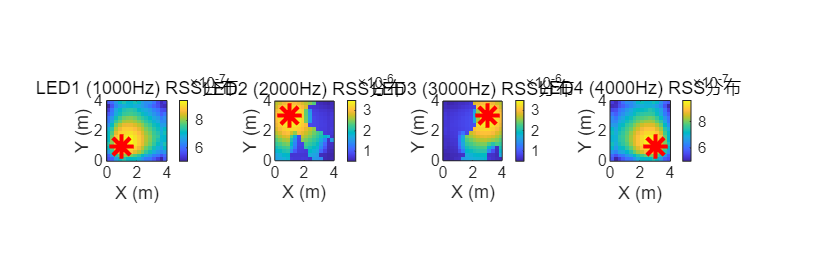


% ===== 图2: RSS指纹热图 =====
figure('Name', 'RSS指纹分布', 'Position', [150, 50, 1200, 400]);
for led_idx = 1:4
    subplot(1, 4, led_idx);
    % 需要将 RSS 按照原始网格位置画热图，这里简单用散点插值也可以，
    % 但为了保持你原始结构，这里用 griddata 做插值。
    [Xg, Yg] = meshgrid(x_grid, y_grid);
    RSS_vals = fingerprint_DB(:, 2+led_idx);
    Zg = griddata(fingerprint_DB(:,1), fingerprint_DB(:,2), RSS_vals, Xg, Yg, 'natural');
    imagesc(x_grid, y_grid, Zg);
    colorbar; axis equal tight;
    set(gca, 'YDir', 'normal');
    xlabel('X (m)'); ylabel('Y (m)');
    title(sprintf('LED%d (%.0fHz) RSS分布', led_idx, LED_freq(led_idx)));
    hold on;
    plot(LED_pos(led_idx,1), LED_pos(led_idx,2), 'r*', 'MarkerSize', 12, 'LineWidth', 2);
end


% ===== 图3: 不同K值的VLP误差CDF对比 =====
figure('Name', 'VLP定位误差CDF', 'Position', [200, 100, 800, 600]);
hold on; grid on;
colors = ['r', 'b', 'g'];
for k_idx = 1:length(K_values)
    errors_sorted = sort(results(k_idx).errors);
    cdf = (1:num_test) / num_test;
    plot(errors_sorted, cdf, [colors(k_idx), '-'], 'LineWidth', 2.5, ...
         'DisplayName', sprintf('K=%d', K_values(k_idx)));

    % 计算统计量
    mean_err = mean(results(k_idx).errors);
    p90_err  = prctile(results(k_idx).errors, 90);
    fprintf('K=%d (VLP): 平均误差=%.3fm, 90%%误差=%.3fm, 最大误差=%.3fm\n', ...
            K_values(k_idx), mean_err, p90_err, max(results(k_idx).errors));
end

K=3 (VLP): 平均误差=0.186m, 90%误差=0.459m, 最大误差=1.558m
K=4 (VLP): 平均误差=0.197m, 90%误差=0.437m, 最大误差=1.428m
K=5 (VLP): 平均误差=0.221m, 90%误差=0.552m, 最大误差=1.488m


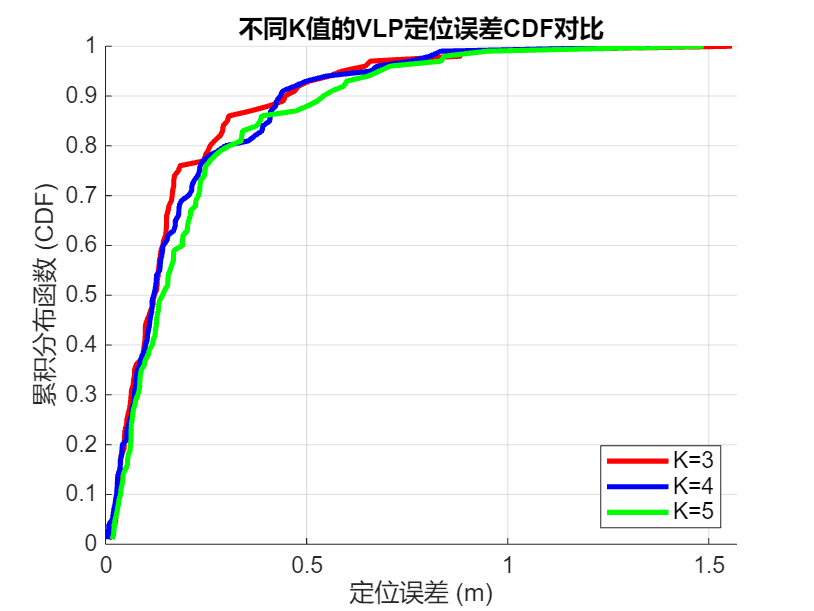

xlabel('定位误差 (m)', 'FontSize', 13);
ylabel('累积分布函数 (CDF)', 'FontSize', 13);
title('不同K值的VLP定位误差CDF对比', 'FontSize', 14, 'FontWeight', 'bold');
legend('Location', 'southeast', 'FontSize', 11);
xlim([0, max(results(2).errors)*1.1]);
set(gca, 'FontSize', 11);

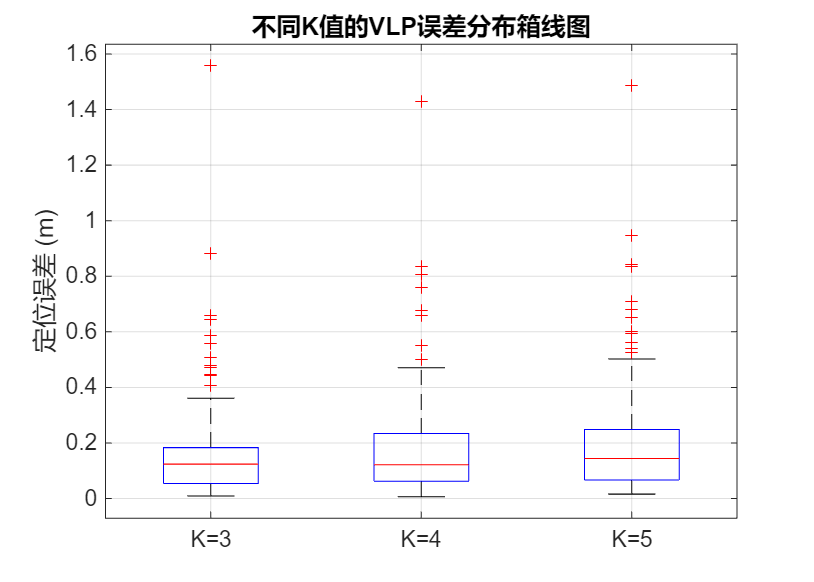


% ===== 图4: K值对比箱线图 =====
figure('Name', 'VLP误差统计对比', 'Position', [250, 150, 700, 500]);
error_data = [results(1).errors, results(2).errors, results(3).errors];
boxplot(error_data, 'Labels', arrayfun(@(x) sprintf('K=%d',x), K_values, 'UniformOutput', false));
ylabel('定位误差 (m)', 'FontSize', 13);
title('不同K值的VLP误差分布箱线图', 'FontSize', 14, 'FontWeight', 'bold');
grid on;
set(gca, 'FontSize', 11);


%% ========================================================================
%  函数定义区
%% ========================================================================

% ===== 函数1: 生成墙面反射单元 =====
function wall_elems = generate_wall_elements(room, N)
    L = room(1); W = room(2); H = room(3);
    dL = L / N; dW = W / N; dH = H / N;
    dA = dL * dH;  % 或 dW * dH
    wall_elems = [];

    % x=0 面
    [Y1, Z1] = meshgrid(linspace(dW/2, W-dW/2, N), linspace(dH/2, H-dH/2, N));
    wall1 = [zeros(N^2,1), Y1(:), Z1(:), ...
             ones(N^2,1), zeros(N^2,2), ...
             dA*ones(N^2,1), ones(N^2,1)];
    % x=L 面
    wall2 = [L*ones(N^2,1), Y1(:), Z1(:), ...
             -ones(N^2,1), zeros(N^2,2), ...
             dA*ones(N^2,1), 2*ones(N^2,1)];
    % y=0, y=W 面
    [X3, Z3] = meshgrid(linspace(dL/2, L-dL/2, N), linspace(dH/2, H-dH/2, N));
    wall3 = [X3(:), zeros(N^2,1), Z3(:), ...
             zeros(N^2,1), ones(N^2,1), zeros(N^2,1), ...
             dA*ones(N^2,1), 3*ones(N^2,1)];
    wall4 = [X3(:), W*ones(N^2,1), Z3(:), ...
             zeros(N^2,1), -ones(N^2,1), zeros(N^2,1), ...
             dA*ones(N^2,1), 4*ones(N^2,1)];

    wall_elems = [wall1; wall2; wall3; wall4];
    wall_elems(:, 9) = 1;  % 有效标志
end

% ===== 函数2: 计算LOS增益（考虑障碍物遮挡） =====
function H = calculate_LOS_gain(LED_pos, PD_pos, m, A_pd, Ts, g, FOV, obstacles)
    % obstacles: [N x 4], 每行 [xmin xmax ymin ymax]
    % 如果传入且非空，则先判断是否被遮挡
    if nargin >= 8 && ~isempty(obstacles)
        if is_blocked_by_obstacles_2D(LED_pos, PD_pos, obstacles)
            H = 0;
            return;
        end
    end

    % 原始 LOS 计算
    vec = PD_pos - LED_pos;
    d = norm(vec);
    if d < 1e-6
        H = 0;
        return;
    end

    % 假设 LED 垂直向下、PD 垂直向上
    cos_phi = abs(vec(3)) / d;
    cos_psi = abs(vec(3)) / d;
    psi = acos(cos_psi);

    if psi > FOV
        H = 0;
        return;
    end

    g_psi = (psi <= FOV) * g;
    H = ((m+1) * A_pd / (2*pi*d^2)) * (cos_phi^m) * Ts * g_psi * cos_psi;
end

% ===== 函数3: 计算NLOS增益 (一次反射，不考虑障碍物遮挡) =====
function H_NLOS = calculate_NLOS_gain(LED_pos, PD_pos, wall_elems, rho, m, A_pd, Ts, g, FOV)
    H_NLOS = 0;
    num_elems = size(wall_elems, 1);

    for i = 1:num_elems
        elem_pos    = wall_elems(i, 1:3);
        elem_normal = wall_elems(i, 4:6);
        dA          = wall_elems(i, 7);

        % LED -> 墙元
        vec1 = elem_pos - LED_pos;
        d1   = norm(vec1);
        if d1 < 1e-6
            continue;
        end
        cos_phi1 = abs(vec1(3)) / d1;
        cos_psi1 = -dot(vec1, elem_normal) / d1;
        if cos_psi1 <= 0
            continue;
        end

        % 墙元 -> PD
        vec2 = PD_pos - elem_pos;
        d2   = norm(vec2);
        if d2 < 1e-6
            continue;
        end
        cos_phi2 = dot(vec2, elem_normal) / d2;
        cos_psi2 = abs(vec2(3)) / d2;
        psi2     = acos(cos_psi2);
        if cos_phi2 <= 0 || psi2 > FOV
            continue;
        end

        g_psi2 = (psi2 <= FOV) * g;

        dH = rho * dA * ((m+1)/(2*pi*d1^2)) * (cos_phi1^m) * cos_psi1 * ...
             (A_pd / (pi*d2^2)) * cos_phi2 * Ts * g_psi2 * cos_psi2;
        H_NLOS = H_NLOS + dH;
    end
end

% ===== 函数4: WKNN定位算法 =====
function pos_est = WKNN_positioning(RSS_measured, DB, K)
    RSS_db = DB(:, 3:6);
    distances = sqrt(sum((RSS_db - repmat(RSS_measured, size(RSS_db,1), 1)).^2, 2));
    [~, idx_sorted] = sort(distances);
    idx_KNN = idx_sorted(1:K);

    epsilon = 1e-9;
    weights = 1 ./ (distances(idx_KNN) + epsilon);
    weights = weights / sum(weights);

    pos_est = sum(weights .* DB(idx_KNN, 1:2), 1);
end

% ===== 函数5: A* 核心算法 =====
function [path_indices, path_found] = AStar_pathfinding(map, start_node, goal_node)

    [rows, cols] = size(map);
    map_size = [rows, cols];

    % 将 [row, col] 转换为线性索引
    start_ind = sub2ind(map_size, start_node(1), start_node(2));
    goal_ind  = sub2ind(map_size, goal_node(1), goal_node(2));

    % 1. 初始化
    gScore = Inf(rows, cols);
    gScore(start_ind) = 0;

    fScore = Inf(rows, cols);

    % 启发函数：欧几里得距离
    [r, c] = ind2sub(map_size, (1:rows*cols)');
    goal_r = goal_node(1);
    goal_c = goal_node(2);
    h = sqrt((r - goal_r).^2 + (c - goal_c).^2);
    h_matrix = reshape(h, rows, cols);
    fScore(start_ind) = h_matrix(start_ind);

    openSet   = false(rows, cols);
    openSet(start_ind) = true;
    closedSet = false(rows, cols);

    cameFrom  = zeros(rows*cols, 1);  % 父节点线性索引
    path_found = false;

    % 2. A* 主循环
    while any(openSet(:))
        fScore_open = fScore;
        fScore_open(~openSet) = Inf;
        [~, current_ind] = min(fScore_open(:));
        [current_r, current_c] = ind2sub(map_size, current_ind);

        if current_ind == goal_ind
            path_found = true;
            break;
        end

        openSet(current_ind)   = false;
        closedSet(current_ind) = true;

        % 遍历邻居（8方向）
        for dr = -1:1
            for dc = -1:1
                if dr == 0 && dc == 0
                    continue;
                end

                neighbor_r = current_r + dr;
                neighbor_c = current_c + dc;

                % 边界检查
                if neighbor_r < 1 || neighbor_r > rows || ...
                   neighbor_c < 1 || neighbor_c > cols
                    continue;
                end

                neighbor_ind = sub2ind(map_size, neighbor_r, neighbor_c);

                % 障碍物，跳过
                if map(neighbor_ind) == 1
                    continue;
                end

                % 已在 closedSet 中
                if closedSet(neighbor_ind)
                    continue;
                end

                move_cost = sqrt(dr^2 + dc^2); % 1 或 sqrt(2)
                tentative_gScore = gScore(current_ind) + move_cost;

                if tentative_gScore < gScore(neighbor_ind)
                    cameFrom(neighbor_ind) = current_ind;
                    gScore(neighbor_ind)   = tentative_gScore;
                    fScore(neighbor_ind)   = tentative_gScore + h_matrix(neighbor_ind);

                    if ~openSet(neighbor_ind)
                        openSet(neighbor_ind) = true;
                    end
                end
            end
        end
    end

    % 3. 回溯路径
    if path_found
        path_linear = reconstructPath_AStar(cameFrom, current_ind);
        [path_rows, path_cols] = ind2sub(map_size, path_linear);
        path_indices = [path_rows, path_cols];
    else
        path_indices = [];
    end
end

% ===== 函数6: 路径回溯 (A*) =====
function path_indices = reconstructPath_AStar(cameFrom, current_ind)
    total_path = current_ind;
    while cameFrom(current_ind) ~= 0
        current_ind = cameFrom(current_ind);
        total_path  = [current_ind; total_path]; %#ok<AGROW>
    end
    path_indices = total_path;
end

% ===== 函数7: 判断 LED-PD 直线路径是否被任一障碍物遮挡 =====
function blocked = is_blocked_by_obstacles_2D(LED_pos, PD_pos, obstacles)
    % 在 x-y 平面上判断 line segment 是否与任一矩形相交
    p1 = LED_pos(1:2);  % [xL, yL]
    p2 = PD_pos(1:2);   % [xP, yP]
    blocked = false;

    if isempty(obstacles)
        return;
    end

    for i = 1:size(obstacles, 1)
        obs  = obstacles(i, :);  % [xmin xmax ymin ymax]
        xmin = obs(1); xmax = obs(2);
        ymin = obs(3); ymax = obs(4);

        % 1) 任一端点在障碍物内部 -> 视为遮挡
        if (p1(1) >= xmin && p1(1) <= xmax && p1(2) >= ymin && p1(2) <= ymax) || ...
           (p2(1) >= xmin && p2(1) <= xmax && p2(2) >= ymin && p2(2) <= ymax)
            blocked = true;
            return;
        end

        % 2) 判断线段 p1-p2 是否与矩形四条边相交
        rect = [ xmin  ymin;
                 xmax  ymin;
                 xmax  ymax;
                 xmin  ymax ];
        for e = 1:4
            a = rect(e, :);
            b = rect(mod(e,4)+1, :);
            if segments_intersect_2D(p1, p2, a, b)
                blocked = true;
                return;
            end
        end
    end
end

% ===== 函数8: 判断两条 2D 线段是否相交 =====
function flag = segments_intersect_2D(p1, p2, p3, p4)
    d1 = direction_2D(p3, p4, p1);
    d2 = direction_2D(p3, p4, p2);
    d3 = direction_2D(p1, p2, p3);
    d4 = direction_2D(p1, p2, p4);

    flag = (((d1 > 0 && d2 < 0) || (d1 < 0 && d2 > 0)) && ...
            ((d3 > 0 && d4 < 0) || (d3 < 0 && d4 > 0)));
end

function d = direction_2D(p1, p2, p3)
    % 计算 (p3 - p1) 相对于 (p2 - p1) 的叉积符号
    d = (p3(1) - p1(1)) * (p2(2) - p1(2)) - ...
        (p3(2) - p1(2)) * (p2(1) - p1(1));
end
